**Visualization of a PPG using sinusoid**

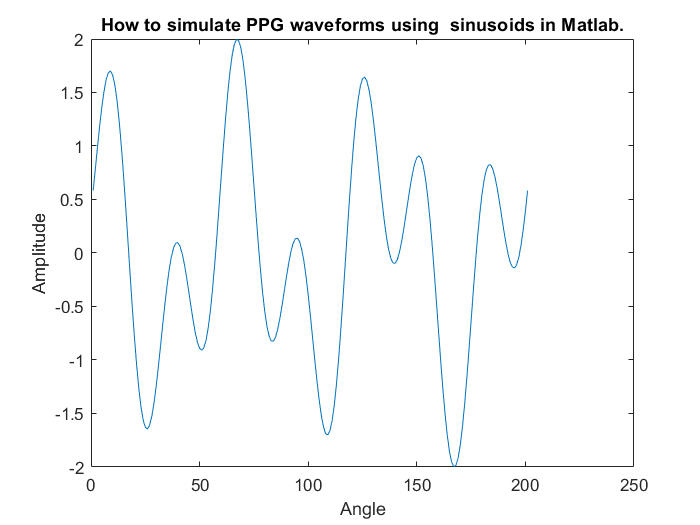

x=0:pi/100:2*pi;
wave_2=cos(x*3)+cos(x*7-2);
figure , plot(wave_2);
xlabel("Angle");
ylabel("Amplitude");
title ("How to simulate PPG waveforms using  sinusoids in Matlab.");

**Visualization of a PPG using Two Gaussians**

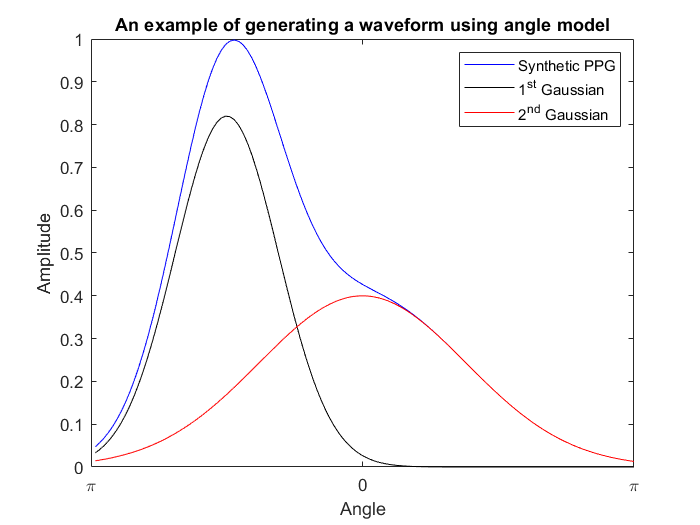

Duration = 1;
Fs = 125; %Sampling Frequency

a = [0.82,0.4];
mu = [-pi/2,0];
sigma = [0.6,1.2];

Samples = Fs/Duration;
V_angle = 2*pi/Samples;
angle = -pi+V_angle :V_angle:pi;
y1 = a(1) * exp(-(((angle-mu(1))/sigma(1)).^2)/2);
y2 = a(2) * exp(-(((angle-mu(2))/sigma(2)).^2)/2);
y = y1 + y2;

figure; plot(angle,y,'b');
hold on; plot(angle,y1,'k');plot(angle,y2,'r-');
xlabel("Angle");
ylabel("Amplitude");
xlim([-pi,pi]);
set(gca,'xtick',[-pi,0,pi],'xticklabel',{'\pi','0','\pi'});
legend("Synthetic PPG","1^{st} Gaussian", "2^{nd} Gaussian");
title("An example of generating a waveform using angle model");

Check file

function up = universal_parameters

fprintf('\n --- Setting up Universal Parameters')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%% PARAMETERS TO BE SPECIFIED %%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Specify the root data directory (where the Matlab file is, and where the
% results will be stored)
up.paths.root_folder = '/Users/petercharlton/Desktop/temp/ppgdiary/'; % note the need for a slash at the end of the path
fprintf('\n   - The results will be stored at:\n   %s', up.paths.root_folder);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%   OTHER PARAMETERS   %%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%   (don't need editing)   %%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

close all

up.paths.conv_data_file = [up.paths.root_folder, 'ppg_diary_pilot_conv_data.mat'];
up.paths.filt_data_file = [up.paths.root_folder, 'filt_data.mat'];
up.paths.beat_data_file = [up.paths.root_folder, 'beat_data.mat'];
up.paths.rec_periods_file = [up.paths.root_folder, 'rec_periods.mat'];
up.paths.trial_outcomes_file = [up.paths.root_folder, 'trial_outcomes.mat'];
up.paths.sample_data_file_1_hour = [up.paths.root_folder, 'PPGdiary1_1_hour_sample.mat'];
up.paths.sample_data_file_1_min = [up.paths.root_folder, 'PPGdiary1_1_min_sample.mat'];
up.paths.sample_data_file_1_pulse = [up.paths.root_folder, 'PPGdiary1_1_pulse_sample.mat'];
up.paths.quality_data_file = [up.paths.root_folder, 'quality_data.mat'];
up.paths.plot_folder = [up.paths.root_folder, 'plots', filesep];
if exist(up.paths.plot_folder), mkdir(up.paths.plot_folder); end

% Filter characteristics: Eliminate VLFs (below resp freqs): For 4bpm cutoff
up.paramSet.elim_vlf.Fpass = 0.157;  % in Hz
up.paramSet.elim_vlf.Fstop = 0.02;   % in Hz     (0.157 and 0.02 provide a - 3dB cutoff of 0.0665 Hz)
up.paramSet.elim_vlf.Fpass = 0.6;  % in Hz
up.paramSet.elim_vlf.Fstop = 0.3;   % in Hz     
up.paramSet.elim_vlf.Dpass = 0.05;
up.paramSet.elim_vlf.Dstop = 0.01;

% Filter characteristics: Eliminate VHFs (above frequency content of signals)
up.paramSet.elim_vhf.Fpass = 38.5;  % in HZ
up.paramSet.elim_vhf.Fstop = 33.12;  % in HZ   (33.12 and 38.5 provide a -3 dB cutoff of 35 Hz)
up.paramSet.elim_vhf.Fpass = 20;  % in HZ
up.paramSet.elim_vhf.Fstop = 15;  % in HZ
up.paramSet.elim_vhf.Dpass = 0.05;
up.paramSet.elim_vhf.Dstop = 0.01;

% Beat detection settings
up.beat_detect.win_length = 10; % in secs
up.beat_detect.win_step_prop = 0.8;

end

function export_sample_data(up)

fprintf('\n --- Exporting sample data')

% load filtered data
load(up.paths.filt_data_file)

% identify one hour of data shortly after an annotation of sleeping
t = (1552865724-1550497798)*1000; % time in ms of sleeping since start
rel_t = [t+0.5*60*1000, t+60.5*60*1000];
rel_els = data.t_ms_rel>=rel_t(1) & data.t_ms_rel<=rel_t(2);

% extract this as a sample dataset
sample.ppg_ir = -1*data.ppg_ir(rel_els);
sample.ppg_red = -1*data.ppg_red(rel_els);
sample.fs = data.fs;
sample.description = 'Infra-red and red PPG recording from PPG Diary Pilot Study. A one-hour recording acquired during sleep.';
clear data

% save data
data = sample;
save(up.paths.sample_data_file_1_hour, 'data')

% save data (1 min sample)
no_els = 1+(sample.fs*60);
start_el = 16*60*sample.fs;
rel_els = start_el:start_el+no_els-1;
S.v = sample.ppg_ir(rel_els);
S.fs = sample.fs;
S.description = 'Infra-red PPG recording from PPG Diary Pilot Study. A one-minute recording acquired during sleep.';
save(up.paths.sample_data_file_1_min, 'S')

% save data (1 pulse wave sample)
rel_els = start_el+172:start_el+339;
S.v = sample.ppg_ir(rel_els);
S.fs = sample.fs;
S.description = 'Infra-red PPG recording from PPG Diary Pilot Study. A recording of a single pulse wave acquired during sleep.';
save(up.paths.sample_data_file_1_pulse, 'S')

end

%function identify_rec_periods(up)
%fprintf('\n --- Identifying recording periods')

Function definitions in a script must appear at the end of the file.
Move all statements after the "export_sample_data" function definition to before the first local function definition.